# Figure composite Acoustic Group 1 Female calls

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
GGPath = dir('/Users/elie/Google Drive*');
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'CallType', 'BatID','MPS_mic', 'MPS_mic_wf', 'MPS_mic_wt')
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'MicAudioGood','TmicAll7');
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'), 'MicFileNum', 'MicFileSampleID', 'OnSetOffsetSample', 'AmpPeriodF','Time_ent','Q1Mic_mean', 'CallDate','Spect_psd', 'Spect_psdf', 'Spect_psd_biosound', 'Spect_psdf_biosound');
DurationElmt = diff(OnSetOffsetSample,1,2)/192000*1000;
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);
load(fullfile(LocalDataDir, 'Data4_DeafBats_PermDFA_AllCalls.mat'), 'PC', 'Score', 'VarExpl')

Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UCT = unique(CallType(~cellfun(@isempty, CallType)));
UCT = UCT([1:4 9 5:8 10:14])

UCT = 14×1 cell array
    {'BB' }
    {'Ba' }
    {'Bu' }
    {'Ch' }
    {'Pi' }
    {'LPi'}
    {'LT' }
    {'PB' }
    {'Pa' }
    {'Ra' }
    {'SB' }
    {'Sq' }
    {'Tr' }
    {'Un' }


UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'LPi')} = 'Loud Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
IndNoCall = cellfun(@isempty, CallType);
CallType(IndNoCall) = {'Un'};
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for BatName, Sex and Deafness
Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end
    
end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

First restrict the MPS spectral frequency to 3 cycles/kHz and normalized all MPS

addpath(genpath('/Users/elie/Documents/CODE/GitHub/umapDistribution'))
IndWf = (MPS_mic_wf*1000)<=3; % Max Spectral frequency taken into account in cycles/kHz
NVoc = sum(MicAudioGood01);
MPS_mic_norm = cell(1,NVoc);
MPS_mic_focus = cell(1,NVoc);
MPS_mic_mean = reshape(mean(MPS_mic(MicAudioGood01,:), 'omitnan')',length(MPS_mic_wf), length(MPS_mic_wt));
IndMicAudioGood = find(MicAudioGood01);
for nn=1:NVoc
    vv=IndMicAudioGood(nn);
    MPS_local = reshape(MPS_mic(vv,:)',length(MPS_mic_wf), length(MPS_mic_wt));
    MPS_local = MPS_local(IndWf,:);
    MPS_mic_norm{nn} = reshape(MPS_local./MPS_mic_mean(IndWf,:), numel(MPS_local),1);
    MPS_mic_focus{nn} = reshape(MPS_local, numel(MPS_local),1);
end
MPS_mic_norm = [MPS_mic_norm{:}]';
MPS_mic_focus = [MPS_mic_focus{:}]';
CCT_mic = CCT(MicAudioGood01,:);

Mdl = fitcdiscr(Score(FemaleLogical,1:100),SexDeafMic(FemaleLogical), 'CrossVal','off', 'Prior', [0.5 0.5]);

Run Manova with all data for plotting purposes

SexDeafMic = SexDeaf(IndMicAudioGood);
FemaleLogical = logical(contains(SexDeafMic, 'F') .* TmicAll7==1);
Npc = 100;
[N_DF, P_DF, StatsDF] = manova1(Score(FemaleLogical,1:Npc),SexDeafMic(FemaleLogical))

N_DF = 1

P_DF = 3.2265e-177

StatsDF = struct with fields:
           W: [100×100 double]
           B: [100×100 double]
           T: [100×100 double]
         dfW: 2486
         dfB: 1
         dfT: 2487
      lambda: 0.6247
       chisq: 1.1462e+03
     chisqdf: 100
    eigenval: [100×1 double]
    eigenvec: [100×100 double]
       canon: [2488×100 double]
       mdist: [2488×1 double]
      gmdist: [2×2 double]
      gnames: {2×1 cell}


[Mean_HDF, Sem_HDF, MeanCI_HDF,Range_HDF, Name_HDF] = grpstats(StatsDF.canon(:,1:N_DF),SexDeafMic(FemaleLogical), {'mean', 'sem', 'meanci', 'range', 'gname'} )

Mean_HDF =    -0.5935
    1.0116


Sem_HDF =     0.0252
    0.0331


MeanCI_HDF =    -0.6429   -0.5441
    0.9466    1.0765


Range_HDF =     8.9859
    7.9284


Name_HDF = 2×1 cell array
    {'DF'}
    {'HF'}


Identify 4 examples of calls with extreme values of DF1 for Hearing and Deaf Females

MicAudioGoodInd = find(MicAudioGood);
NumEx = 4;
MicAudioGoodInd1 = MicAudioGoodInd(logical((TmicAll7==1) .* contains(SexDeaf(MicAudioGoodInd), 'F')));
IndHFHighDF1 = MicAudioGoodInd1(logical((-StatsDF.canon(:,1)<-2) .* strcmp(SexDeaf(MicAudioGoodInd1), 'HF')));
IndDFLowDF1 = MicAudioGoodInd1(logical((-StatsDF.canon(:,1)>2) .* strcmp(SexDeaf(MicAudioGoodInd1), 'DF')));

RandInd = randperm(min(length(IndHFHighDF1), length(IndDFLowDF1)));
BatID_DF_Examples = BatID(IndDFLowDF1(RandInd));
BatID_HF_Examples = BatID(IndHFHighDF1(RandInd));
% Select Indices that correspond to two bats for each group
BatID_DF = unique(BatID_DF_Examples);
BatID_HF = unique(BatID_HF_Examples);
RandInd_DF = nan(NumEx,1);
RandInd_HF = RandInd_DF;
for bb=1:length(BatID_DF)
    II = find(contains(BatID_DF_Examples,BatID_DF{bb}),2);
    RandInd_DF((bb*2-1) : bb*2) = RandInd(II);
    II = find(contains(BatID_HF_Examples,BatID_HF{bb}),2);
    RandInd_HF((bb*2-1) : bb*2) = RandInd(II);
end
    
ExampleHF.Spectro = cell(NumEx,1);
ExampleHF.Fo = cell(NumEx,1);
ExampleHF.To = cell(NumEx,1);
ExampleHF.Sound = cell(NumEx,1);
% ExampleHF.AmpPeriodF = nan(NumEx,1);
ExampleHF.TimeEnt = nan(NumEx,1);
ExampleHF.DFA1 = nan(NumEx,1);
ExampleHF.BatID = cell(NumEx,1);
ExampleDF = ExampleHF;


for ii=1:NumEx
    fprintf(1, 'Example %d\n',ii)
    % Hearing Females examples (High DFA1)
%     ExampleHF.DurationElmt(ii) = DurationElmt(IndHFHighDF1(RandInd_HF(ii)));
%     ExampleHF.AmpPeriodF(ii) = AmpPeriodF(IndHFHighDF1(RandInd_HF(ii)));
    ExampleHF.TimeEnt(ii) = Time_ent(IndHFHighDF1(RandInd_HF(ii)));
    ExampleHF.DFA1(ii) = -StatsDF.canon(MicAudioGoodInd1==IndHFHighDF1(RandInd_HF(ii)));
    WhoFile = dir(fullfile(BaseDataDir, ['20' num2str(CallDate(IndHFHighDF1(RandInd_HF(ii))))], 'audiologgers', sprintf('DeSa_%s_*_%d_%d*200.pdf', num2str(CallDate(IndHFHighDF1(RandInd_HF(ii)))),  MicFileNum(IndHFHighDF1(RandInd_HF(ii))), MicFileSampleID(IndHFHighDF1(RandInd_HF(ii))))));
    Ind_ = strfind(WhoFile.name, '_');
    SetNum = WhoFile.name((Ind_(7)+1):(Ind_(8)-1));
    ExpTime = WhoFile.name((Ind_(2)+1):(Ind_(3)-1));
    DataFilename = dir(fullfile(BaseDataDir, ['20' num2str(CallDate(IndHFHighDF1(RandInd_HF(ii))))], 'audiologgers', sprintf('%d_*_VocExtractData%s_200.mat', CallDate(IndHFHighDF1(RandInd_HF(ii))), SetNum)));
    DataFile = load(fullfile(DataFilename.folder, DataFilename.name));
    if any(cellfun(@isempty,DataFile.BioSoundFilenames(:,2)))
        IndBS = find(~cellfun(@isempty,DataFile.BioSoundFilenames(:,2)));
        CallsInd = IndBS(contains(DataFile.BioSoundFilenames(IndBS,2), sprintf('DeSa_%s_%s_voc_%d_%d', num2str(CallDate(IndHFHighDF1(RandInd_HF(ii)))), ExpTime,  MicFileNum(IndHFHighDF1(RandInd_HF(ii))), MicFileSampleID(IndHFHighDF1(RandInd_HF(ii))))));
    else
        CallsInd = find(contains(DataFile.BioSoundFilenames(:,2), sprintf('DeSa_%s_%s_voc_%d_%d', num2str(CallDate(IndHFHighDF1(RandInd_HF(ii)))), ExpTime,  MicFileNum(IndHFHighDF1(RandInd_HF(ii))), MicFileSampleID(IndHFHighDF1(RandInd_HF(ii))))));
    end
    
    for vv=1:length(CallsInd)
        if any(DataFile.BioSoundCalls{CallsInd(vv),1}.MeanQ1t == Q1Mic_mean(IndHFHighDF1(RandInd_HF(ii))))
            CallInd = CallsInd(vv);
            break
        end
    end
    [~,Name,~] = fileparts(DataFile.BioSoundFilenames{CallInd,2});
    BatInd = strfind(Name,'Bat');
    ExampleHF.BatID{ii} = Name(BatInd+(3:7));
                
    if isfield(DataFile.BioSoundCalls{CallInd,1}, 'spectro_elmts')
        elmt = find(DataFile.BioSoundCalls{CallInd,1}.MeanQ1t == Q1Mic_mean(IndHFHighDF1(RandInd_HF(ii))));
        ExampleHF.Spectro{ii} = DataFile.BioSoundCalls{CallInd,1}.spectro_elmts{elmt};
        ExampleHF.Fo{ii} = DataFile.BioSoundCalls{CallInd,1}.fo_elmts{elmt};
        ExampleHF.To{ii} = DataFile.BioSoundCalls{CallInd,1}.to_elmts{elmt};
        ExampleHF.Sound{ii} = DataFile.BioSoundCalls{CallInd,1}.sound(DataFile.BioSoundCalls{CallInd,1}.OnOffSets_elmts(elmt,1):DataFile.BioSoundCalls{CallInd,1}.OnOffSets_elmts(elmt,2));
    else
        elmt=1;
        ExampleHF.Spectro{ii} = DataFile.BioSoundCalls{CallInd,1}.spectro;
        ExampleHF.Fo{ii} = DataFile.BioSoundCalls{CallInd,1}.fo;
        ExampleHF.To{ii} = DataFile.BioSoundCalls{CallInd,1}.to;
        ExampleHF.Sound{ii} = DataFile.BioSoundCalls{CallInd,1}.sound;
    end
    
    % Deaf males examples (high DFA1)
%     ExampleDF.DurationElmt(ii) = DurationElmt(IndDFLowDF1(RandInd_DF(ii)));
%     ExampleDF.AmpPeriodF(ii) = AmpPeriodF(IndDFLowDF1(RandInd_DF(ii)));
    ExampleDF.TimeEnt(ii) = Time_ent(IndDFLowDF1(RandInd_DF(ii)));
    ExampleDF.DFA1(ii) = -StatsDF.canon(MicAudioGoodInd1==IndDFLowDF1(RandInd_DF(ii)));
    WhoFile = dir(fullfile(BaseDataDir, ['20' num2str(CallDate(IndDFLowDF1(RandInd_DF(ii))))], 'audiologgers', sprintf('DeSa_%s_*_%d_%d*200.pdf', num2str(CallDate(IndDFLowDF1(RandInd_DF(ii)))),  MicFileNum(IndDFLowDF1(RandInd_DF(ii))), MicFileSampleID(IndDFLowDF1(RandInd_DF(ii))))));
    Ind_ = strfind(WhoFile.name, '_');
    SetNum = WhoFile.name((Ind_(7)+1):(Ind_(8)-1));
    ExpTime = WhoFile.name((Ind_(2)+1):(Ind_(3)-1));
    DataFilename = dir(fullfile(BaseDataDir, ['20' num2str(CallDate(IndDFLowDF1(RandInd_DF(ii))))], 'audiologgers', sprintf('%d_*_VocExtractData%s_200.mat', CallDate(IndDFLowDF1(RandInd_DF(ii))), SetNum)));
    DataFile = load(fullfile(DataFilename.folder, DataFilename.name));
    if any(cellfun(@isempty,DataFile.BioSoundFilenames(:,2)))
        IndBS = find(~cellfun(@isempty,DataFile.BioSoundFilenames(:,2)));
        CallsInd = IndBS(contains(DataFile.BioSoundFilenames(IndBS,2), sprintf('DeSa_%s_%s_voc_%d_%d', num2str(CallDate(IndDFLowDF1(RandInd_DF(ii)))), ExpTime,  MicFileNum(IndDFLowDF1(RandInd_DF(ii))), MicFileSampleID(IndDFLowDF1(RandInd_DF(ii))))));
    else
        CallsInd = find(contains(DataFile.BioSoundFilenames(:,2), sprintf('DeSa_%s_%s_voc_%d_%d', num2str(CallDate(IndDFLowDF1(RandInd_DF(ii)))), ExpTime,  MicFileNum(IndDFLowDF1(RandInd_DF(ii))), MicFileSampleID(IndDFLowDF1(RandInd_DF(ii))))));
    end
    
    for vv=1:length(CallsInd)
        if any(DataFile.BioSoundCalls{CallsInd(vv),1}.MeanQ1t == Q1Mic_mean(IndDFLowDF1(RandInd_DF(ii))))
            CallInd = CallsInd(vv);
            break
        end
    end
    [~,Name,~] = fileparts(DataFile.BioSoundFilenames{CallInd,2});
    BatInd = strfind(Name,'Bat');
    ExampleDF.BatID{ii} = Name(BatInd+(3:7));
                
    if isfield(DataFile.BioSoundCalls{CallInd,1}, 'spectro_elmts')
        elmt = find(DataFile.BioSoundCalls{CallInd,1}.MeanQ1t == Q1Mic_mean(IndDFLowDF1(RandInd_DF(ii))));
        ExampleDF.Spectro{ii} = DataFile.BioSoundCalls{CallInd,1}.spectro_elmts{elmt};
        ExampleDF.Fo{ii} = DataFile.BioSoundCalls{CallInd,1}.fo_elmts{elmt};
        ExampleDF.To{ii} = DataFile.BioSoundCalls{CallInd,1}.to_elmts{elmt};
        CallType = DataFile.ManualCallType{CallInd}{elmt};
        ExampleDF.Sound{ii} = DataFile.BioSoundCalls{CallInd,1}.sound(DataFile.BioSoundCalls{CallInd,1}.OnOffSets_elmts(elmt,1):DataFile.BioSoundCalls{CallInd,1}.OnOffSets_elmts(elmt,2));
    else
        elmt=1;
        ExampleDF.Spectro{ii} = DataFile.BioSoundCalls{CallInd,1}.spectro;
        ExampleDF.Fo{ii} = DataFile.BioSoundCalls{CallInd,1}.fo;
        ExampleDF.To{ii} = DataFile.BioSoundCalls{CallInd,1}.to;
        CallType = DataFile.ManualCallType{CallInd}{elmt};
        ExampleDF.Sound{ii} = DataFile.BioSoundCalls{CallInd,1}.sound;
    end
end

Example 1
Example 2
Example 3
Example 4


save(fullfile(LocalDataDir, 'Data4_Figure2_DeafBats_FemaleGroup1.mat'), 'ExampleDF','ExampleHF','RandInd_DF','RandInd_HF');

Figure!

Fig1=figure(1);
clf
set(gcf,'Visible','on')
T=tiledlayout(12,19,'TileSpacing','compact');

% The positive direction of the DF1 axis in the MPS space
N=nexttile(1,[4,3]);
PC_DF = PC(:,1:Npc) * StatsDF.eigenvec(:,1:N_DF);
PC_DF = -reshape(PC_DF,sum(IndWf), length(MPS_mic_wt));
[CB1,Im1,~]=plot_mps(PC_DF, MPS_mic_wf(IndWf), MPS_mic_wt, 60, nan, 0, [0 max(MPS_mic_wf(IndWf)*10^3)], [-150 150]);
% title('DFA1 in the MPS space positive values')
Cmap = flip([ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)]);
colormap(Cmap)
caxis([-9 9].*10^-2)
xlabel('')
xticklabels('')
yticklabels('')
ylabel('')
N.FontSize = 8;

% The negative direction of the DF1 axis in the MPS space
N=nexttile(153,[4,3]);
[CB3, Im3,~]=plot_mps(-PC_DF, MPS_mic_wf(IndWf), MPS_mic_wt, 60, nan, 0, [0 max(MPS_mic_wf(IndWf)*10^3)], [-150 150]);
% title('DFA1 in the MPS space positive values')
Cmap = flip([ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)]);
colormap(Cmap)
caxis([-9 9].*10^-2)
N.FontSize = 8;

% The average MPS for male calls in cat1
N=nexttile(77, [4,3]);
MPS_mic_norm1F = MPS_mic_norm(logical((TmicAll7==1) .* contains(SexDeaf(IndMicAudioGood), 'F')),:);
MPS_mic_norm_1F_mean = reshape(mean(MPS_mic_norm1F, 'omitnan')',length(MPS_mic_wf(IndWf)), length(MPS_mic_wt));
[CB2,Im2,~]=plot_mps(MPS_mic_norm_1F_mean, MPS_mic_wf(IndWf), MPS_mic_wt, 60, nan, 1, [0 max(MPS_mic_wf(IndWf)*10^3)],[-150 150]);
xlabel('')
ylabel('')
xticklabels('')
yticklabels('')
N.FontSize = 8;

% The swarmchart of DF1 values for females color coded with AmpPeriodF
N=nexttile(4, [12,8]);
BatID_Mic = BatID(IndMicAudioGood);
% DurationElmt_Mic1F = DurationElmt(IndMicAudioGood(logical((TmicAll7==1).*contains(SexDeaf(IndMicAudioGood), 'F'))));
TimeEnt_Mic1F = Time_ent(IndMicAudioGood(logical((TmicAll7==1).*contains(SexDeaf(IndMicAudioGood), 'F'))));
x=3;
Legend=cell(length(BatName),1);
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(TimeEnt_Mic1F,x, 0.8,1);

for bb=1:6
    BatName_local = num2str(BatName(bb));
    Ind = strcmp(BatID_Mic(FemaleLogical), BatName_local);
    hold on
    swarmchart(bb*ones(sum(Ind),1),-StatsDF.canon(Ind,1),30,Colors(Ind,:),'o','filled','MarkerFaceAlpha',0.7,'MarkerEdgeAlpha',0.7)
    SepStr = strsplit(BatSexDeaf{bb});
    if strcmp(SepStr{1}(1), 'H')
        Legend{bb} = ['S' SepStr{2}(1) BatName_local(end)]; 
    else
        Legend{bb} = ['K' SepStr{2}(1) BatName_local(end)]; 
    end
end
ylabel('DFA 1', 'FontSize',8);
ylim([-6 6])
set(gca, 'XTick', 1:6,'XTickLabel', Legend(1:6), 'XLim', [0 7], 'FontSize',8)
set(gca,'YTick', [-6 0 6],'YTickLabel',[-6 0 6])
set(gca, 'Color', [0.9 0.9 0.9])
cc=colorbar();
cc.Label.String = 'Time entropy';
cc.FontSize = 8;
cc.Location = 'north';
N.Colormap = GRAD;
YTL = 0.8:0.1:1; % Set which label we want to see
YT_new = (YTL + Slide)*10^x / ceil((MaxColVal+Slide)*10^x);
set(cc, 'YTickLabel',YTL,'YTick',YT_new)
cc.Units = 'inches';
cc.Position(4) = 0.1;
cc.Position(2) = cc.Position(2)+0.2;
hold on
hline(0, '--k')
hold off

% The examples for Deaf Females
DBNOISE =50;
f_low = 0;
F_high = 50000; % This is the max frequency used to calculate the spectrogram and heance to obtain Q1
TileNum = [12 16 69 73];
fprintf(1, 'Values of examples chosen from left to right and top to bottom, by row\n')

Values of examples chosen from left to right and top to bottom, by row


for ii=1:NumEx
    
    AP=audioplayer(ExampleDF.Sound{ii}./(max(abs(ExampleDF.Sound{ii}))),192000);
    play(AP)
    pause()
    N=nexttile(TileNum(ii), [3,4]);
    logB = ExampleDF.Spectro{ii};
    maxB = max(max(logB));
    minB = maxB-DBNOISE;
    IM=imagesc(ExampleDF.To{ii}*1000,ExampleDF.Fo{ii},logB);          % to is in seconds
    axis xy;
    caxis('manual');
    caxis([minB maxB]);
    cmap = spec_cmap();
    colormap(IM.Parent, cmap);
    v_axis = axis;
    v_axis(3)=f_low;
    v_axis(4)=F_high;
    axis(v_axis);
%     xlabel('time (ms)')
%     ylabel('Frequency');
%     set(N,'YTick',0:25000:F_high,'YTickLabel',0:25:F_high/10^3)
    set(N,'YTick',[],'YTickLabel',{})
%     title(sprintf('KM%s %.1f', ExampleDM.BatID{ii}(end), ExampleDM.DFA1(ii)), 'FontSize',9)
    fprintf(1,'Ex%d KF%s DFA=%.1f  DurationElmt=%.1f\n', ii, ExampleDF.BatID{ii}(end), ExampleDF.DFA1(ii), ExampleDF.DurationElmt(ii))
%     hold on
%     L=hline(ExampleDF.Q1MicMean(ii), 'k--');
%     L.LineWidth=2;
    N.FontSize = 8;
    hold off
%     N=nexttile(TileNum(ii)+3, [3 1]);
%     plot(Spect_psd_biosound{IndDMHighDF1(RandInd(ii))}, Spect_psdf_biosound{IndDMHighDF1(RandInd(ii))},'LineWidth',2)
%     ylim([0 20000])
%     xlabel('Power')
%     set(N,'YTick',[],'YTickLabel',{})
%     ylabel('Frequency')
end

Ex1 KF3 DFA=2.2  DurationElmt=88.0
Ex2 KF3 DFA=2.2  DurationElmt=NaN
Ex3 KF7 DFA=2.9  DurationElmt=NaN
Ex4 KF7 DFA=2.3  DurationElmt=NaN



% The examples for Hearing Females
TileNum = [126 130 183 187];
for ii=1:NumEx
    
    AP=audioplayer(ExampleHF.Sound{ii}./(max(abs(ExampleHF.Sound{ii}))),192000);
    play(AP)
    pause()
    N=nexttile(TileNum(ii), [3,4]);
    logB = ExampleHF.Spectro{ii};
    maxB = max(max(logB));
    minB = maxB-DBNOISE;
    IM=imagesc(ExampleHF.To{ii}*1000,ExampleHF.Fo{ii},logB);          % to is in seconds
    axis xy;
    caxis('manual');
    caxis([minB maxB]);
    cmap = spec_cmap();
    colormap(IM.Parent, cmap);
    v_axis = axis;
    v_axis(3)=f_low;
    v_axis(4)=F_high;
    axis(v_axis);
    if ii>2
        xlabel('time (ms)');
    end
    if ii==3
        ylabel('Frequency (kHz)', 'FontSize',8);
        set(N,'YTick',0:25000:F_high,'YTickLabel',0:25:F_high/10^3)
    else
        set(N,'YTick',[],'YTickLabel',{})
    end
%     hold on
%     L=hline(ExampleHF.Q1MicMean(ii), 'k--');
%     L.LineWidth=2;
    N.FontSize = 8;
    hold off
    fprintf(1,'Ex%d SF%s DFA=%.1f  DurationElmt=%.1f\n', ii, ExampleHF.BatID{ii}(end),ExampleHF.DFA1(ii), ExampleHF.DurationElmt(ii))
%     title(sprintf('SM%s %.1f', ExampleHM.BatID{ii}(end),ExampleHM.DFA1(ii)), 'FontSize',9)
%     N= nexttile(TileNum(ii)+3, [3 1]);
%     plot(Spect_psd_biosound{IndHMLowDF1(RandInd(ii))}, Spect_psdf_biosound{IndHMLowDF1(RandInd(ii))},'LineWidth',2)
%     ylim([0 20000])
%     xlabel('Power')
%     set(N,'YTick',[],'YTickLabel',{})
%     ylabel('Frequency')
end

Ex1 SF8 DFA=-2.3  DurationElmt=88.0
Ex2 SF8 DFA=-2.1  DurationElmt=NaN
Ex3 SF6 DFA=-2.7  DurationElmt=NaN
Ex4 SF6 DFA=-3.8  DurationElmt=NaN


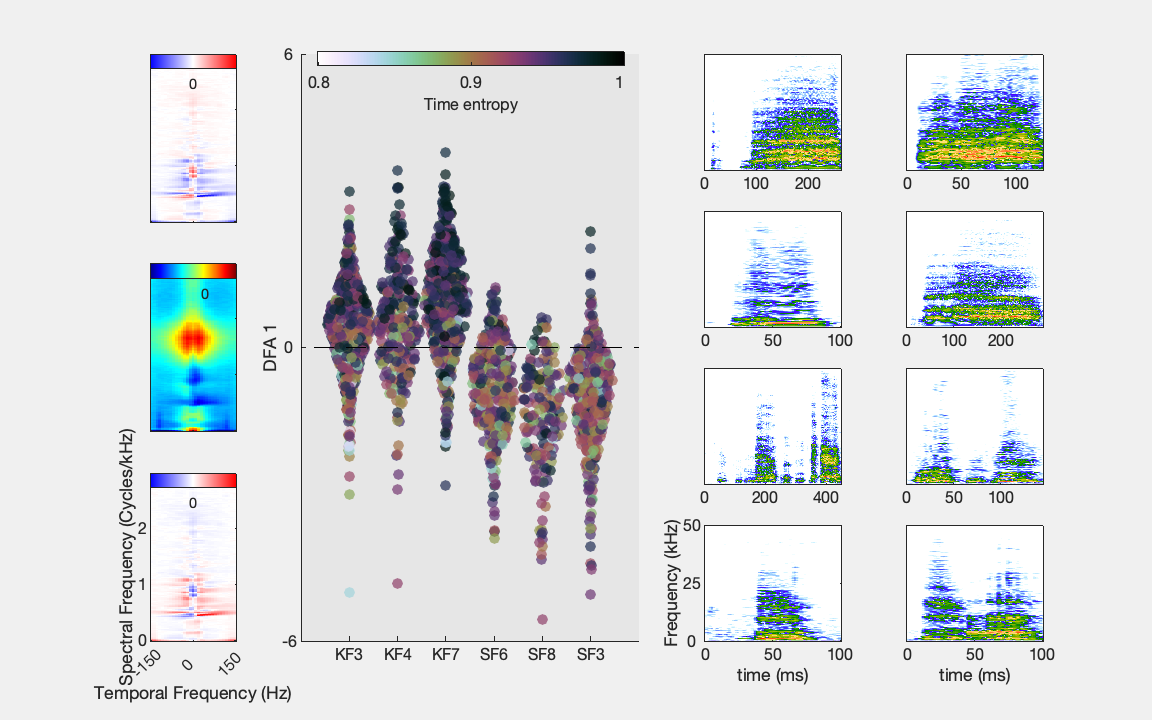

Im1.Parent.Units = 'inches';
CB1.Position(1:3) = Im1.Parent.Position(1:3) + [0 Im1.Parent.Position(4)-0.1 0];
Im2.Parent.Units = 'inches';
CB2.Position(1:3) = Im2.Parent.Position(1:3) + [0 Im2.Parent.Position(4)-0.1 0];
Im3.Parent.Units = 'inches';
CB3.Position(1:3) = Im3.Parent.Position(1:3) + [0 Im3.Parent.Position(4)-0.1 0];

Fig1.PaperOrientation = 'landscape';
Fig1.Units = 'inches';
Fig1.Position(3:4) = [8 5];
Fig1.PaperSize = [8 5];
print(Fig1,fullfile(Path2Paper,'Figure2_FemaleCallsGroup1.pdf'),'-dpdf','-fillpage')

function [Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(VARcol,x, MinColVal, MaxColVal)
    % Getting VARZ ready for plotting.
    % If VARcol is always a non-null
    % integer then you can use it directly in cubehelix by specifying x=1
    % otherwise, the function first multiplies VARcol by 10^x to make sure its
    % variability is maximized after ceiling it to an integer
    if nargin<2
        x=3;% here I'm doing *1000 as an example
    end

    if nargin<3
        MinColVal=0;
    end

    if nargin<4
        MaxColVal = max(VARcol);
    end

%     if nargin<5
%         LogToggle=0;
%     end
    % Make sure you don't have nan or infinite values
    if MinColVal && any(VARcol<MinColVal)
        warning('%d data point(s) cannot be represented by the chosen lower limit for the colorscale', sum(VARcol<MinColVal))
        VARcol(VARcol<MinColVal) = nan;
    end
    VARcol(isinf(VARcol))=nan;
    VARcolout = VARcol(~isnan(VARcol));
%     if LogToggle==2
%         VARcol = log2(VARcol);
%     elseif LogToggle==10
%         VARcol = log10(VARcol);
%     end
    

    % Scale your minimum value as 0 or min Val
    Slide = 0;
    if ~MinColVal && sum(VARcolout<=0)>0
        Slide = -min(VARcolout)+ 10^(-x);
    elseif MinColVal==1
        Slide = -min(VARcolout)+ 10^(-x);
    elseif MinColVal
        Slide = -MinColVal+ 10^(-x);
    end

    VARcol_cube = ceil((VARcolout+Slide)*10^x);
    %GRAD=cubehelix(max(VARZ_cube));%Note that you can choose the values of...
    ...your gradient by doing cubehelix_view and then specifying the values in...
        ...the function, for instance: GRAD=cubehelix(max(VARZ_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -1.1, 1.5, 0.5, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
    GRAD=cubehelix(ceil((MaxColVal+Slide)*10^x),0.5, -1.5, 1, 1, [1,0]);

    NU = length(VARcol); % this is the number of points you have in your plot
    Colors = nan(NU, size(GRAD,2));
    Nancount=0;
    for jj=1:NU
        if isnan(VARcol(jj))
            Nancount=Nancount+1;
            continue
        else
            Colors(jj,:) = GRAD(VARcol_cube(jj-Nancount),:); % for each dot you call the line in the gradient of color that correspond to the value in Z
        end
    end
    
% figure()
%     
%     cc=colorbar();
%     colormap(GRAD)
%     set(gca, 'Color', [0.7 0.7 0.7])
%     
%     YTL = get(cc, 'YTickLabel');
%     YTL_new = ceil((MaxColVal+Slide)*10^x) .* str2double(YTL)/10^x - Slide;
%     if LogToggle==2
%         YTL_new = 2.^YTL_new;
%     elseif LogToggle==10
%         YTL_new = 10.^YTL_new;
%     end
%     YTL_new = num2str(round(YTL_new.*10^(x-1))./10^(x-1));
%     set(cc, 'YTickLabel',YTL_new)%here you correct the value of the z axis that you artificially multiplied by 10^x

end


function [CB,Im,MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
    if nargin<4
        DBNOISE=60;
    end

    if nargin<6
        Log=1;
    end

    if nargin<7
        YLim = [0 max(Wf*10^3)];
    end
    if nargin<8
        XLim = [min(Wt) max(Wt)];
    end
    if nargin<5
        CLim = nan;
    end
    if nargin<9
        TwoDfilter=0;
    end
    
    Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
    Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
    MPS = MPS(Wf_i, Wt_i);
    Wf_local = Wf(Wf_i);
    Wt_local = Wt(Wt_i);
    if Log
        MPS4plot = 10*log10(MPS);
        MaxMPS = max(max(MPS4plot));
        MinMPS = MaxMPS-DBNOISE;
        MPS4plot(MPS4plot < MinMPS) = MinMPS;
    else
        MPS4plot = MPS; 
    end

    if TwoDfilter
        MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
    end
    
    %             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
    Im = imagesc(MPS4plot);
    axis xy
    colormap(Im.Parent,'jet');
    CB=colorbar();
    CB.YTick=0;
    CB.YTickLabel=0;
    CB.Units = 'inches';
    CB.Location='north';
    CB.Position(4) = 0.1;
    CB.Position(2) = CB.Position(2) + 0.2;
    xlabel('Temporal Frequency (Hz)')
    ylabel('Spectral Frequency (Cycles/kHz)')
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_local*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(ceil(Wt_local*10^-1))*10^1;
    XTickLabel = [-MaxWt 0 MaxWt];
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    if ~isnan(CLim)
        PlotMPS = gca;
        PlotMPS.CLim = CLim;
    end
end